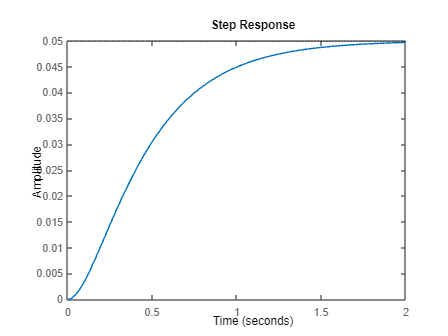

t = 0:0.01:2;
sys = tf(1, [1 10 20]);
step(sys, t);

stepinfo(sys)

ans = struct with fields:
         RiseTime: 0.8843
    TransientTime: 1.5894
     SettlingTime: 1.5894
      SettlingMin: 0.0452
      SettlingMax: 0.0500
        Overshoot: 0
       Undershoot: 0
             Peak: 0.0500
         PeakTime: 3.2966


## **Using P only Controller**

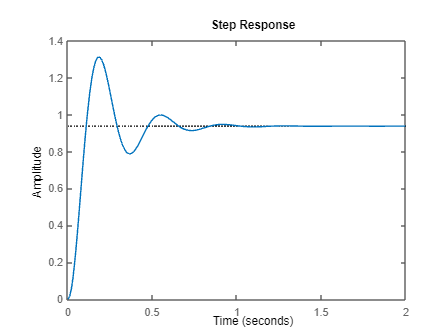

K_p = 300;
C = pid(K_p);
T = feedback(C*sys, 1);
t = 0:0.01:2;
step(T,t);

stepinfo(T)

ans = struct with fields:
         RiseTime: 0.0727
    TransientTime: 0.7724
     SettlingTime: 0.7724
      SettlingMin: 0.7871
      SettlingMax: 1.3131
        Overshoot: 40.0588
       Undershoot: 0
             Peak: 1.3131
         PeakTime: 0.1842


## ** Using P - D Controller**

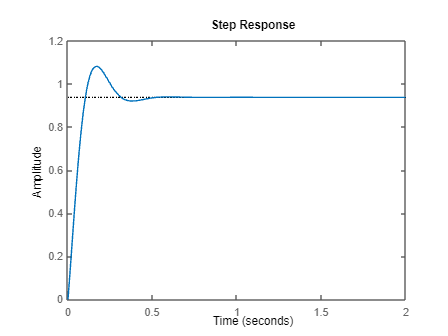

Kp = 300;
Kd = 10;
C = pid(Kp, 0, Kd);
T = feedback(C*sys, 1);

t = 0:0.01:2;
step(T,t);

stepinfo(T)

ans = struct with fields:
         RiseTime: 0.0777
    TransientTime: 0.2897
     SettlingTime: 0.2897
      SettlingMin: 0.8490
      SettlingMax: 1.0813
        Overshoot: 15.3418
       Undershoot: 0
             Peak: 1.0813
         PeakTime: 0.1704


## **Using P - I Controller**

Kp = 30;
Ki = 70;
C = pid(Kp, Ki)

C =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 30, Ki = 70
 
Continuous-time PI controller in parallel form.



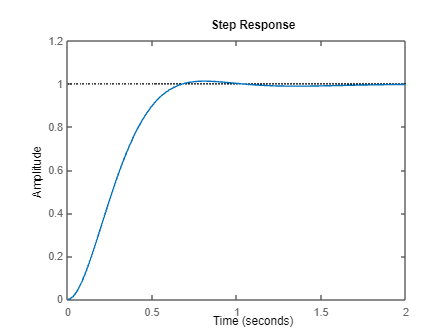

T = feedback(C*sys, 1);

t = 0:0.01:2;
step(T, t);

stepinfo(T)

ans = struct with fields:
         RiseTime: 0.4084
    TransientTime: 0.6182
     SettlingTime: 0.6182
      SettlingMin: 0.9058
      SettlingMax: 1.0126
        Overshoot: 1.2588
       Undershoot: 0
             Peak: 1.0126
         PeakTime: 0.8143
